# **Exploratory Data Analysis - *****Fault vs No Fault***

% Initialization
bus_number = '634';
folder_name = 'Fault_Data_5';

% Loading No-Fault Data
no_fault_file = fullfile(folder_name, 'NoFault', ['Bus_', bus_number, '.csv']);
no_fault_data = readtable(no_fault_file);
time_no_fault = no_fault_data.Time;
voltages_no_fault = [no_fault_data.FaultyBusVoltages_1, no_fault_data.FaultyBusVoltages_2, no_fault_data.FaultyBusVoltages_3];
currents_no_fault = [no_fault_data.FaultyBusCurrents_1, no_fault_data.FaultyBusCurrents_2, no_fault_data.FaultyBusCurrents_3];

% Loading Fault Data
fault_types = {'AB', 'BC', 'AC', 'AG', 'BG', 'CG', 'ABC', 'ABG', 'BCG', 'ACG', 'ABCG'};
fault_type = fault_types{7};  % Select fault type 
fault_file = fullfile(folder_name, fault_type, ['Bus_', bus_number, '.csv']);
fault_data_table = readtable(fault_file);  % Load fault data into a table

% Extracting time, voltages, and currents for the selected fault type
time_fault = fault_data_table.Time;
voltages_fault = [fault_data_table.FaultyBusVoltages_1, ...
                  fault_data_table.FaultyBusVoltages_2, ...
                  fault_data_table.FaultyBusVoltages_3];
currents_fault = [fault_data_table.FaultyBusCurrents_1, ...
                  fault_data_table.FaultyBusCurrents_2, ...
                  fault_data_table.FaultyBusCurrents_3];

% Ensuring the lengths match before plotting
if length(time_no_fault) ~= length(time_fault)
    min_length = min(length(time_no_fault), length(time_fault));
    
    % Truncate to the minimum length to match time vectors
    time_no_fault = time_no_fault(1:min_length);
    voltages_no_fault = voltages_no_fault(1:min_length, :);
    time_fault = time_fault(1:min_length);
    voltages_fault = voltages_fault(1:min_length, :);
end

% Plotting Phase-A (1) Voltage Comparison - No Fault vs Fault
figure;
plot(time_no_fault, voltages_no_fault(:, 1), 'b-', 'LineWidth', 2); hold on;  % Blue line for No-Fault

plot(time_fault, voltages_fault(:, 1), 'r--', 'LineWidth', 1.5);  % Red dashed line for Fault 'A'

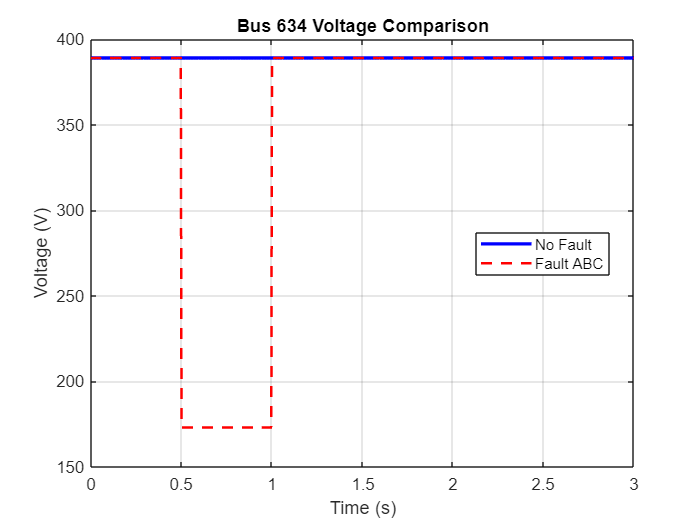

title(['Bus ', bus_number, ' Voltage Comparison']);
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('No Fault', ['Fault ', fault_type], 'Location', 'best');  % Update the legend with both plots
grid on; 